clear
clc

load('sizing')

%parameters from poster
W_S= 2973 %

W_S = 2973

C_cruise=295.1 %m/s

C_cruise = 295.1000

M_cruise=0.75

M_cruise = 0.7500

V_cruise=C_cruise*M_cruise %m/s

V_cruise = 221.3250

rho_cruise= 0.302748958

rho_cruise = 0.3027

W_cruise_W_total=0.842

W_cruise_W_total = 0.8420

Max_takeoff_weight=3740 %kg

Max_takeoff_weight = 3740

%mu_cruise=2.969*10^(-7)
mu_cruise=1.45*10^(-5)

mu_cruise = 1.4500e-05

character_c=0.6096

character_c = 0.6096

CL_design_cruise=( (W_cruise_W_total)*(W_S) )/ (0.5*rho_cruise*V_cruise^2)

CL_design_cruise = 0.3376


% L_over_D=Cl/cd;
% plot( Alpha, Cl)
% ylabel('Cl')
% xlabel('alpha')
% [CL_Alpha_curve, gof] = CL_ALPHA_FIT(Alpha, Cl)
% 
% Cl_design=CL_Alpha_curve(4.25)



% Cl_max=max(Cl)



%mach
sweep_25=18.1692

sweep_25 = 18.1692

M_DD=0.7438

M_DD = 0.7438

M_DD_Eff=M_DD*sqrt(cosd(sweep_25))

M_DD_Eff = 0.7250

AR=7.8

AR = 7.8000

x=cosd(22)

x = 0.9272


Cl_design_a=(CL_design_cruise/(0.9*0.95))/cosd(sweep_25)

Cl_design_a = 0.4156



Km=1.05

Km = 1.0500


%lambda_opt=0.45*(0.85)^(-0.036*sweep_angle)
lambda_opt=0.45*exp(-0.036*sweep_25)

lambda_opt = 0.2340

lambda_min=0.2*(AR)^(0.25)*(cosd(sweep_25)^2)

lambda_min = 0.3017

SP=(Max_takeoff_weight*9.8)/(W_S) 

SP = 12.3283

mainwing.b = sqrt(AR*SP) 

mainwing = struct with fields:
    b: 9.8062



lambda=lambda_min

lambda = 0.3017


mainwing.Croot= (2*12.34086)/(9.811*(1+lambda));
mainwing.Ctip=lambda*mainwing.Croot;
C_mean=(2/3) * mainwing.Croot* ((1+lambda+lambda^2)/(1+lambda))

C_mean = 1.3785


%c_dist
m=(0-mainwing.b/2)/(mainwing.Croot/mainwing.Ctip)

m = -1.4794


y_bar=(mainwing.b/6)*((1+2*lambda)/(1+lambda))

y_bar = 2.0132


t_c= 0.3*cosd(sweep_25)*((1-((5+M_DD_Eff^2)/(5+(Km-0.25*Cl_design_a)^2))^3.5)*((sqrt(1-M_DD_Eff^2)/M_DD_Eff^2)))^(2/3)

t_c = 0.1178


Re= (rho_cruise * V_cruise * C_mean )/ mu_cruise

Re = 6.3702e+06

twist=-3

twist = -3


[mainwing.sweepLE] = sweep_angle(sweep_25,0,25,AR,lambda);
[mainwing.sweepTE] = sweep_angle(sweep_25,100,25,AR,lambda);

% i_w_mac=1
% i_w= (y_bar/(b/2))*twist*(x_position) + i_w_mac
alpha_0=-3

alpha_0 = -3

CL_cruise=0.4809

CL_cruise = 0.4809


Cl_alpha=(1.6-0.4)/((16*(pi/180)--0*(pi/180))) %issue find clalpha

Cl_alpha = 4.2972

i_w= (CL_cruise/Cl_alpha)+alpha_0 +0.4*twist

i_w = -4.0881


i_mac=1

i_mac = 1

x_span=[0:mainwing.b/2];
span_twist=((twist)/(mainwing.b/2))*x_span +i_mac+1.20939

span_twist =     2.2094    1.5975    0.9857    0.3738   -0.2381


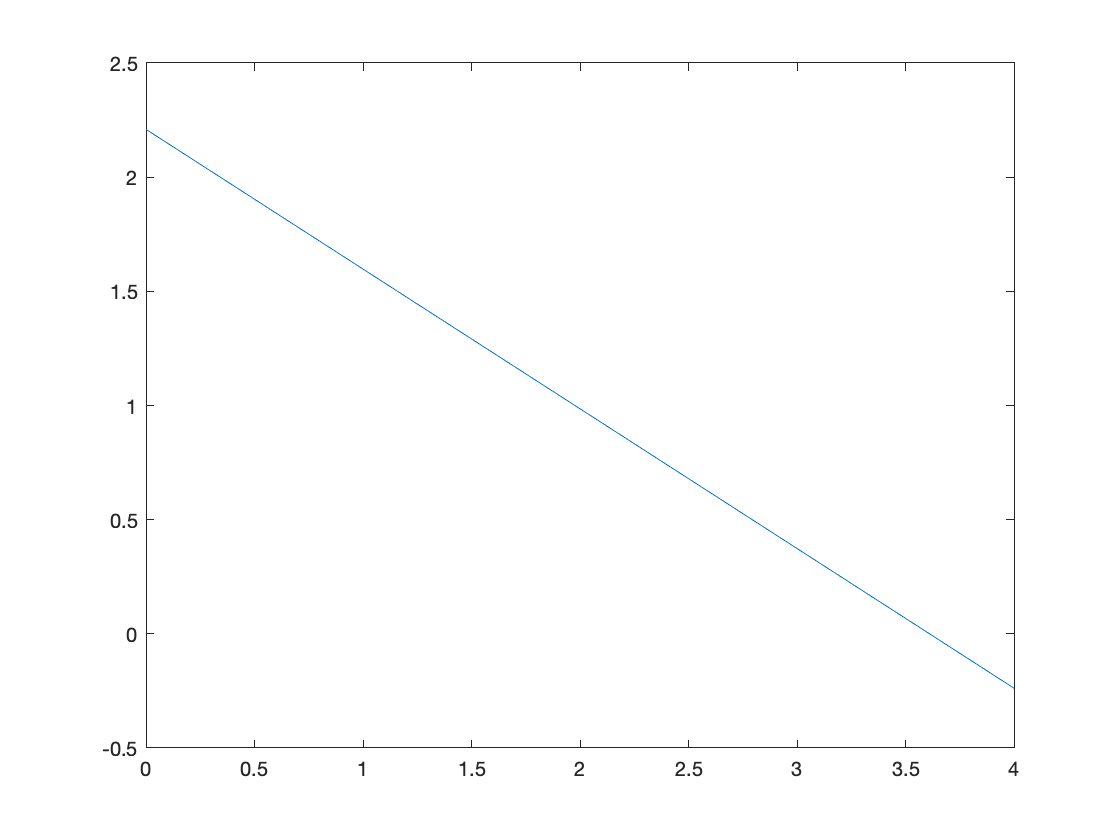

figure
plot(x_span,span_twist)


i_w_method=((twist*y_bar)/(mainwing.b/2)) +i_mac+1.20939

i_w_method = 0.9776

CLmax=1.6

CLmax = 1.6000

CLmax_eff=0.9*CLmax*cosd(sweep_25)

CLmax_eff = 1.3682

delta_y=19.3*t_c %for 65 series

delta_y = 2.2731


CLmax_takeooff = 1.9

CLmax_takeooff = 1.9000

Clmax_landing = 2.4

Clmax_landing = 2.4000

if CLmax_takeooff<Clmax_landing
    q=Clmax_landing
else
    q=CLmax_takeooff
end

q = 2.4000

CL_req_inc=CLmax-q

CL_req_inc = -0.8000

%need 1.0669

%30% of the wing must be allocated to aileron placement for sufficient controllability




m=((2*(mainwing.Ctip-mainwing.Croot))/mainwing.b);
m2=mainwing.sweepLE*(pi/180);
mainwing.HDL_PERC=0.7689;
mainwing.HDL_Croot=(1-mainwing.HDL_PERC)*mainwing.Croot;
mainwing.HDL_Ctip=(1-mainwing.HDL_PERC)*mainwing.Ctip;
[mainwing.sweepHDL]= sweep_angle(sweep_25,mainwing.HDL_PERC*100,25,AR,lambda);


sref=((mainwing.Croot+mainwing.Ctip)/2)*mainwing.b;
%aileron starts at 70 of span
mainwing.aileron_start_top=0.7*mainwing.b/2;
mainwing.aileron_ypos_top=tand(mainwing.sweepHDL)*mainwing.aileron_start_top;
mainwing.aileron_Croot=(1-mainwing.HDL_PERC)*(((2*(mainwing.Ctip-mainwing.Croot))/mainwing.b)*mainwing.aileron_start_top +mainwing.Croot);
saileron=0.5*(mainwing.aileron_Croot+(1-mainwing.HDL_PERC)*mainwing.Ctip)*(mainwing.b-mainwing.aileron_start_top);
mainwing.aileron_start_TE=0.7*mainwing.b/2;
mainwing.aileron_ypos_TE=tand(mainwing.sweepTE)*mainwing.aileron_start_TE;
%1.52/2
mainwing.HDL_start=1.52/2 + 0.05*mainwing.b %therefore 0.05 not including fueselage

mainwing = struct with fields:
                    b: 9.8062
                Croot: 1.9326
                 Ctip: 0.5831
              sweepLE: 21.6510
              sweepTE: 6.9488
             HDL_PERC: 0.7689
            HDL_Croot: 0.4466
             HDL_Ctip: 0.1348
             sweepHDL: 10.5060
    aileron_start_top: 3.4322
     aileron_ypos_top: 0.6365
        aileron_Croot: 0.2283
     aileron_start_TE: 3.4322
      aileron_ypos_TE: 0.4183
            HDL_start: 1.2503


C_HDL_start_root=((2*(mainwing.Ctip-mainwing.Croot))/mainwing.b)*(mainwing.HDL_start) +mainwing.Croot

C_HDL_start_root = 1.5885

C_70=((2*(mainwing.Ctip-mainwing.Croot))/mainwing.b)*(0.7*mainwing.b*0.5) +mainwing.Croot

C_70 = 0.9880

sflapped=(((C_HDL_start_root+C_70)/2)*(0.7*mainwing.b-mainwing.HDL_start))

sflapped = 7.2321


mainwing.C_HDL_root=(1-mainwing.HDL_PERC)*(((2*(mainwing.Ctip-mainwing.Croot))/mainwing.b)*mainwing.HDL_start +mainwing.Croot);



x_dist=[0:mainwing.b/2]

x_dist =      0     1     2     3     4


chord_dist=((2*(mainwing.Ctip-mainwing.Croot))/mainwing.b)*x_dist +mainwing.Croot

chord_dist =     1.9326    1.6574    1.3821    1.1069    0.8317


c_mac=((2*(mainwing.Ctip-mainwing.Croot))/mainwing.b)*y_bar +mainwing.Croot

c_mac = 1.3785

delta_CL=q-CLmax_eff

delta_CL = 1.0318


syms x sweep_hdl
C_dist=((2*(mainwing.Ctip-mainwing.Croot))/mainwing.b)*x+mainwing.Croot

$$C\_dist = \frac{8703594417306081}{4503599627370496}-\frac{4958027463294625\,x}{18014398509481984}$$

c_flap_ext=((CL_req_inc*sref)/(0.9*1.3*sflapped))*(1/cosd(sweep_hdl))*C_dist

$$c\_flap\_ext = \frac{5252095617064461\,\left(\frac{4958027463294625\,x}{18014398509481984}-\frac{8703594417306081}{4503599627370496}\right)}{4503599627370496\,\cos\left(\frac{\pi \,{\mathrm{sweep}}_{\mathrm{hdl}}}{180}\right)}$$


%delta_Cl=1.3*((c_dash)/chord_dist)

%CLeff is the 1.0669, delta_cl = 1.3cdash/c then find the other in terms of
%cf
%delta_CL=0.9*1.3*((c_dash)/chord_dist*(sflapped/sref)*cosd(mainwing.sweepHDL)
%c_dash=delta_CL*0.9*1.3*chord_dist*(sref/sflapped)*(1/cosd(mainwing.sweepHDL))
syms sweep_hdl_find
[mainwing.sweepHDL] = sweep_angle(sweep_25,75,25,AR,lambda);
HDL_coeff=1.6

HDL_coeff = 1.6000

k=(delta_CL*sref) / (0.9*HDL_coeff*sflapped*cosd(sweep_hdl_find)) %c'/c

$$k = \frac{7164660007644481}{5862655713752640\,\cos\left(\frac{\pi \,{\mathrm{sweep}}_{\mathrm{hdl},\mathrm{find}}}{180}\right)}$$

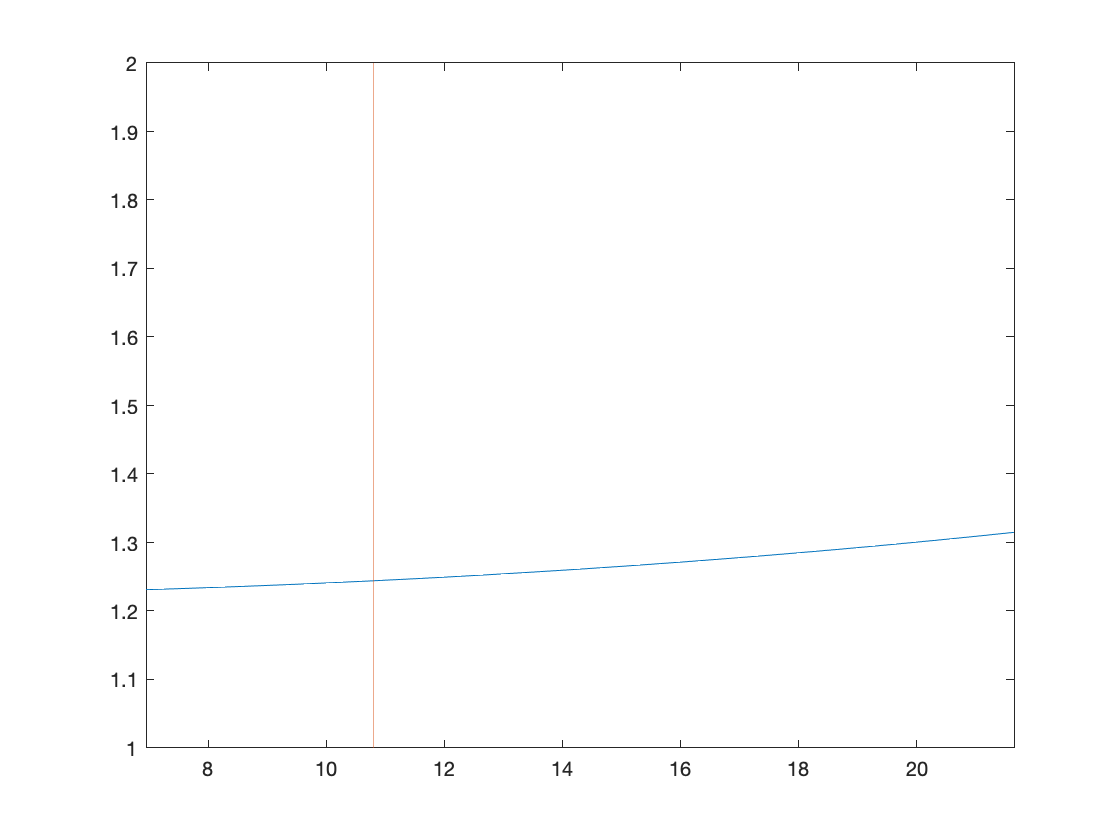

% fplot(@(sweep_hdl_find) k)
fplot(k, [mainwing.sweepTE, mainwing.sweepLE])
hold on
plot([mainwing.sweepHDL, mainwing.sweepHDL],[1,2])

k=(delta_CL*sref) / (0.9*HDL_coeff*sflapped*cosd(mainwing.sweepTE))

k = 1.2311

%k=cbar/c
cbar_root=k*mainwing.Croot

cbar_root = 2.3793

cf=cbar_root-mainwing.Croot

cf = 0.4467

f=cf/mainwing.Croot

f = 0.2311

perc_chord=(mainwing.Croot-cf)/mainwing.Croot

perc_chord = 0.7689

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [617 599 560 420]
       Units: 'pixels'

  Show all properties


rhs_wing =          0         0
         0    1.9326
    4.9031   -0.0137
    4.9031   -0.5969
         0         0


lhs_wing =          0         0
         0    1.9326
   -4.9031   -0.0137
   -4.9031   -0.5969
         0         0


aileron_start = 3.4322

C_HDL_root = 1.5885

rhs_wing_hdl =     1.2503   -0.1524
    1.2503    0.2147
    3.4322   -0.1900
    3.4322   -0.4183
         0         0


lhs_wing_hdl =    -1.2503   -0.1524
   -1.2503    0.2147
   -3.4322   -0.1900
   -3.4322   -0.4183
         0         0


rhs_wing_aileron =     3.4322   -0.4183
    3.4322   -0.1900
    4.9031   -0.4704
    4.9031   -0.6052
    3.4322   -0.4183


lhs_wing_aileron =    -3.4322   -0.4183
   -3.4322   -0.1900
   -4.9031   -0.4704
   -4.9031   -0.6052
   -3.4322   -0.4183


fues = 0.7600

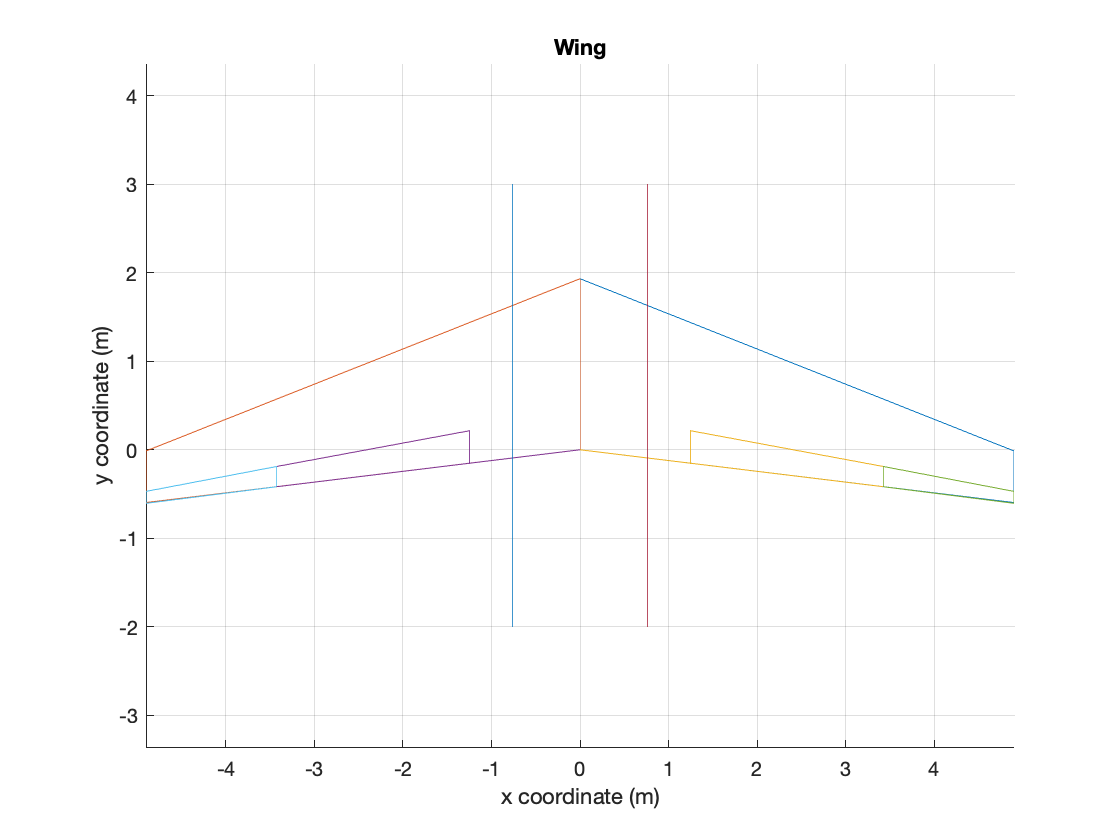

fig =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [617 599 560 420]
       Units: 'pixels'

  Show all properties




[fig] = hdl(mainwing)


%s_exposed=
%s_wet=s_exposed*(1.977+0.52(t_c))

wing.b = mainwing.b;
wing.Croot = mainwing.Croot;
wing.Ctip = mainwing.Ctip ;
wing.sweepLE = mainwing.sweepLE;
wing.sweepTE = mainwing.sweepTE;
wing.HDL_PERC = mainwing.HDL_PERC;
wing.HDL_Croot = mainwing.HDL_Croot;
wing.HDL_Ctip = mainwing.HDL_Ctip;
wing.sweepHDL = mainwing.sweepHDL;
wing.aileron_start_top = mainwing.aileron_start_top;
wing.aileron_ypos_top = mainwing.aileron_ypos_top;
wing.aileron_Croot = mainwing.aileron_Croot;
wing.aileron_start_TE = mainwing.aileron_start_TE;
wing.aileron_ypos_TE = mainwing.aileron_ypos_TE;
wing.HDL_start = mainwing.HDL_start;
wing.C_HDL_root = mainwing.C_HDL_root;



save('wing','wing')


